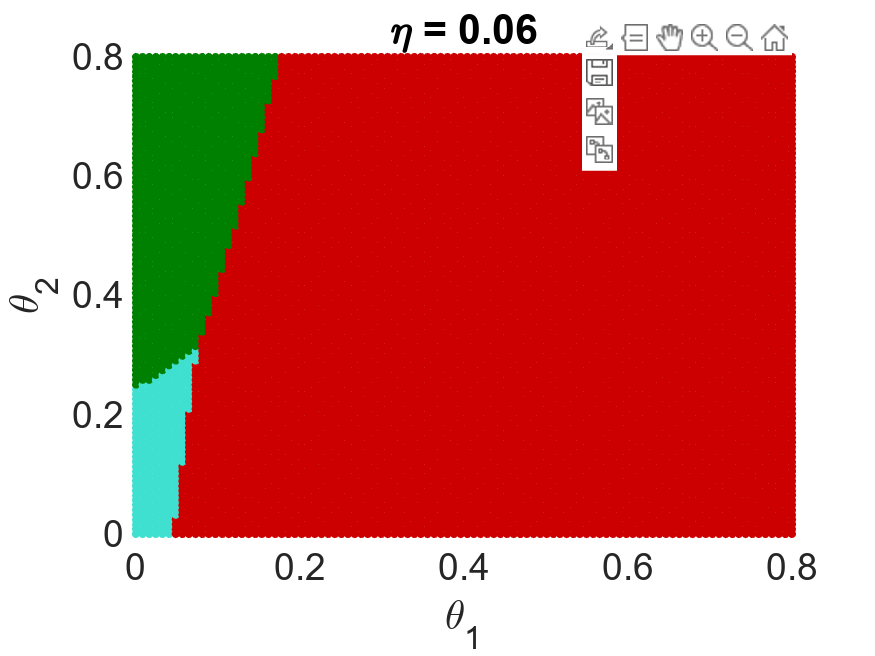

clear;
clc;
close all;
clf;
hold on;

% --- Parámetros fijos del sistema ---
alpha1 = 0.00137; beta1 = 0.07;   gamma1 = 0.01; mu1 = 0.01;
alpha2 = 0.0011;  beta2 = 0.29;   gamma2 = 0.01; mu2 = 0.01;
alpha3 = 0.001;   beta3 = 0.1;
tau = 0.0995;
C = 146.9;

% Condición inicial p_90
x0 = [15.4667; 0.0790; 8.9326];

% Tiempo de simulación
tspan = [0 1000];

% Grilla de parámetros
theta1_vals = linspace(0, 0.8, 100);
theta2_vals = linspace(0, 0.8, 100);

eta    = 0.06; 
T = 2;        % período de tala (2 = año por medio)
tol = 1e-5;  % umbral para considerar especie viva

for i = 1:length(theta1_vals)
    for j = 1:length(theta2_vals)
        theta1 = theta1_vals(i);
        theta2 = theta2_vals(j);

        % Definir sistema con eta fija
        sistema = @(t, x) [
            (alpha1 * x(1) * (C - sum(x))) / (1 + gamma1 * x(3)) ...
                - x(1) * (beta1 + mu1 * x(3) - theta1); 
            (alpha2 * x(2) * (C - sum(x)) * (1 + tau * x(1))) / (1 + gamma2 * x(3)) ...
                - x(2) * (beta2 + mu2 * x(3) - theta2);
            alpha3 * x(3) * (C - sum(x)) - (beta3 + eta * 0.5 * (1 + cos(2 * pi * t / T))) * x(3)
        ];

        % Simular dinámica
        [~, x] = ode45(sistema, tspan, x0);
        xf = x(end,:);

        % Verificar extinción/vida
        if any(xf < -1e-5)
            color = [0.5 0.5 0.5];  % gris - valores negativos
        else
            x1v = xf(1) > tol;
            x2v = xf(2) > tol;
            x3v = xf(3) > tol;

            % Codificar color por combinación de especies
            if ~x1v && ~x2v && ~x3v
                color = [0 0 0];        % negro - extinción total
            elseif ~x1v && ~x2v && x3v
                color = [0 0 1];        % azul - solo 3
            elseif ~x1v && x2v && ~x3v
                color = [0 0.5 0];        % verde - solo 2
            elseif ~x1v && x2v && x3v
                color = [0.5 0.25 0];   % marrón - 2 y 3
            elseif x1v && ~x2v && ~x3v
                color = [0.8 0 0];        % rojo - solo 1
            elseif x1v && ~x2v && x3v
                color = [1 1 0];        % amarillo - 1 y 3
            elseif x1v && x2v && ~x3v
                color = [0.251 0.878 0.816]; % turqueza - 1 y 2
            elseif x1v && x2v && x3v
                color = [1 0.5 0];      % naranja - coexistencia total
            else
                color = [0.5 0.5 0.5];  % gris - caso raro
            end
        end

        % Graficar punto
        plot(theta1, theta2, '.', 'Color', color, 'MarkerSize', 12);
    end
end

% Mejorar gráfico
xlabel('\theta_1');
ylabel('\theta_2');
title(['\eta = ', num2str(eta)]);
axis([0 0.8 0 0.8]);
grid on;
drawnow;

ax = gca;
ax.FontSize = 16;